addpath('final')
addpath('prelab')
setup_lab_ip02_spg
dt = 1e-3;
X0(4) = pi/2;
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Part (i)

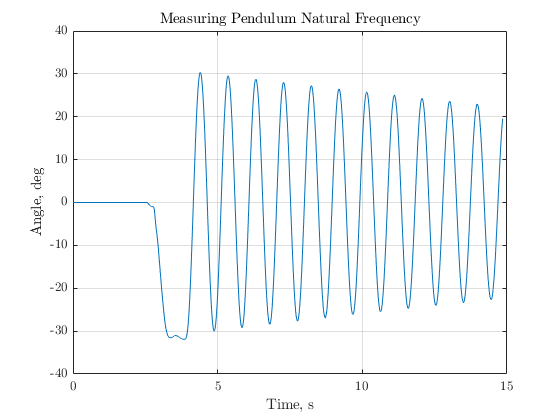

theta1_1 = load('Theta1_1');
alpha1_1 = theta1_1.Theta.signals.values;
t1_1 = theta1_1.Theta.time;
plot(t1_1,rad2deg(alpha1_1))
grid on
title("Measuring Pendulum Natural Frequency")
ylabel("Angle, deg")
xlabel("Time, s")

wn = (13.94-4.4)/10 * 2*pi

wn = 5.9942

## Part (iii)

K3_prelab = place(A,B,[-2-3i, -2+3i, -1 -15])

K3_prelab =     2.9304   -5.6420   -3.6179   -1.9520


K3_2 = load('K3_2'); K3_2 = K3_2.K

K3_2 =    128  -175    65     6


theta3_2 = load('Theta3_2');
alpha3_2 = theta3_2.Theta.signals.values;
t3_2 = theta3_2.Theta.time;
plot(t3_2-2.5,rad2deg(alpha3_2))
grid on
title("Alpha vs Time, Experiment 3.1")
ylabel("Angle, deg")
xlabel("Time, s")
hold on
specs3_2 = stepinfo(alpha3_2,t3_2,0);
settlingtime_prelab = 2.44

settlingtime_prelab = 2.4400

settlingtime_experiement = specs3_2.SettlingTime-2.5

settlingtime_experiement = 2.5305

alpha3_2dot = diff(alpha3_2)/dt;
alpha3_2dotinit = 4.6024

alpha3_2dotinit = 4.6024

K = K3_2;
X0(4) = alpha3_2dotinit;
sim('s_spg_pp')

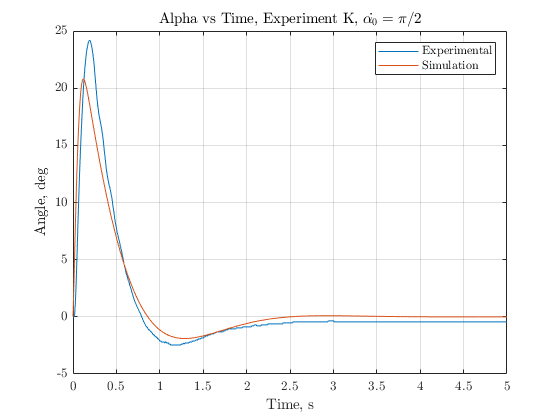

plot(alpha3_2_sim.Time,alpha3_2_sim.Data)
title("Alpha vs Time, Experiment K, $\dot{\alpha_{0}}=\pi/2$")
xlim([0,5])
ylabel("Angle, deg")
xlabel("Time, s")
legend('Experimental','Simulation')
grid on
hold off

K = K3_prelab;
X0(4) = pi/2;
sim('s_spg_pp')
plot(alpha3_2_sim.Time,alpha3_2_sim.Data)
title("Alpha vs Time, Simulation 3.1, $\dot{\alpha_{0}}=\pi/2$")
xlim([0,5])
ylabel("Angle, deg")
xlabel("Time, s")
grid on
hold on
K = K3_2;
sim('s_spg_pp')
plot(alpha3_2_sim.Time,alpha3_2_sim.Data)
legend('Prelab K','Experimental K','Experimental')

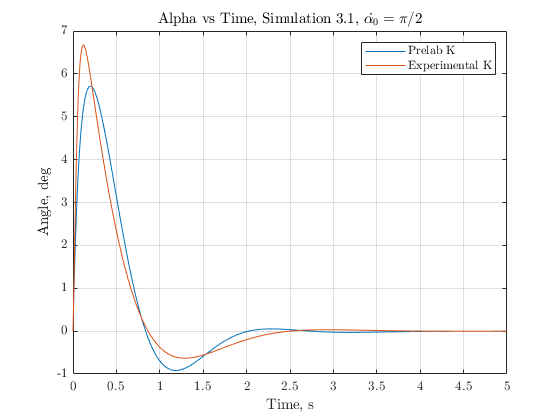

hold off

## Part (iv)

K4_prelab = place(a,b,[-4-6i, -4+6i,-10,-6,-8])

K4_prelab =   200.5502   -6.5686   29.9545    4.0304 -375.0856


K4_2 = load('K4_2'); K4_2 = K4_2.K

K4_2 =    73.3580  -29.6897   19.3690    1.4389  -86.5582


settlingtime_prelab4 = 2.72

settlingtime_prelab4 = 2.7200

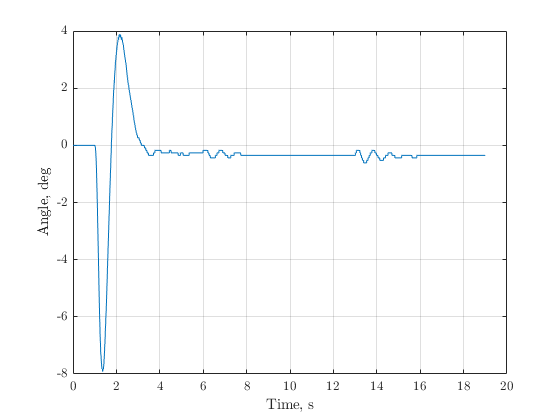

theta4_2 = load('theta4_2');
alpha4_2 = theta4_2.Theta.signals.values;
t4_2 = theta4_2.Theta.time;
plot(t4_2,rad2deg(alpha4_2))
title('')
grid on
xlabel('Time, s')
ylabel('Angle, deg')

specs4_2 = stepinfo(alpha4_2,t4_2,0)

specs4_2 = struct with fields:
        RiseTime: 0
    SettlingTime: NaN
     SettlingMin: -0.1381
     SettlingMax: 0.0675
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.1381
        PeakTime: 1.3590


settlingtime4_2_slider = 4.521 - .968

settlingtime4_2_slider = 3.5530

K = K4_2;
sim('aae364gantry2')

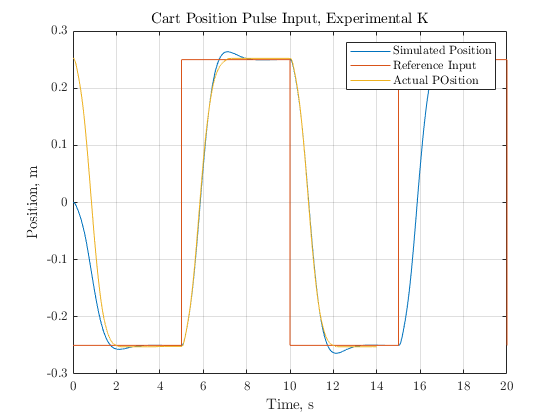

alpha4_2_sim = angle.data;
pos4_2_sim = possy.data;
t4_2_sim = possy.time;
plot(t4_2_sim,pos4_2_sim)
title("Cart Position Pulse Input, Experimental K")
xlabel('Time, s')
ylabel('Position, m')

xlim([0 20])
grid on
hold on
xc4_2_pulse = load('Cartpostion4_2Pulse');
t4_2_pulse = xc4_2_pulse.Cart_position.time-20;
xc_4_2_pulse = xc4_2_pulse.Cart_position.signals.values-.25;
plot(t4_2_pulse-5,xc_4_2_pulse)
legend('Simulated Position','Reference Input','Actual POsition')
hold off

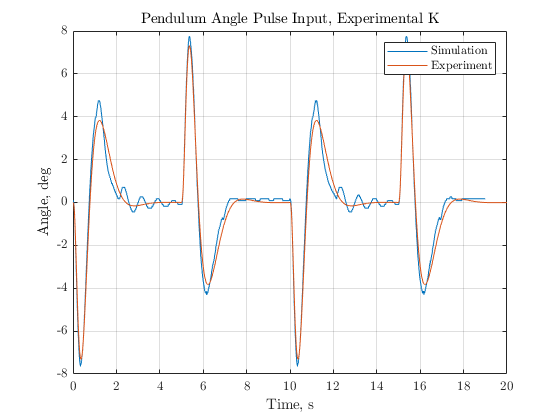

theta4_2_pulse = load('Theta4_2Pulse');
alpha4_2_pulse = theta4_2_pulse.Theta.signals.values;
t4_2_pulse = theta4_2_pulse.Theta.time-20;
plot(t4_2_pulse,rad2deg(alpha4_2_pulse))
title('Pendulum Angle Pulse Input, Experimental K')
xlabel('Time, s')
ylabel('Angle, deg')
grid on
hold on
xlim([0 20])
plot(t4_2_sim-5,alpha4_2_sim)
legend('Simulation','Experiment')
grid on